# **Robo: Bridge of Doom Challenge**

### **Authors: Berwin Lan and Cara Mulrooney**

## **Exercise 21.1**

1. For the Bridge of Doom, plot the parametric curve that defines the centerline of the bridge.

2. On the same figure, plot the unit tangent and unit normal vectors at several points along the curve. You should have starter code to help with this in the Robo Homework 1 assignment.

clc;

% Load data
encoder_data = table2array(readtable("encoder_data.csv"));

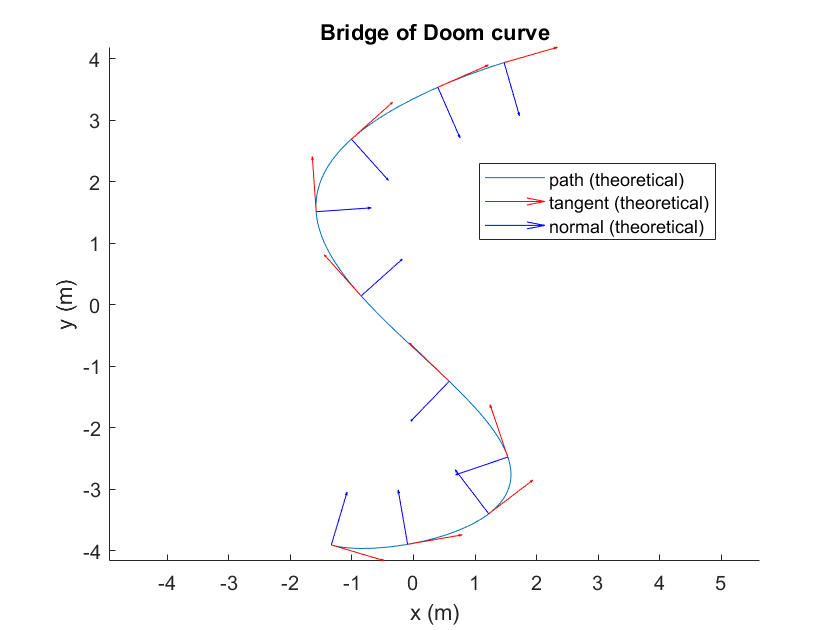

timeseconds = encoder_data(9:end,1);
timeseconds = timeseconds - timeseconds(1);
encoderLeftmeters = encoder_data(9:end,2);
encoderRightmeters = encoder_data(9:end,3);

% The position equations
dilation = 0.10;

% Equations
syms t 
ri = 4 * 0.396*cos(2.65*((dilation*t) + 1.4)); % x-component of vector
rj = 4 * -0.99*sin((dilation*t) + 1.4);         % y-component of vector
rk = 0 * (dilation*t);                         % z-component of vector
r = [ri, rj, rk];

% Find tangent vector
dr = diff(r, t);
T_hat=simplify(dr ./ norm(dr));

% Find normal vector
dT_hat=diff(T_hat,t);
N_hat=simplify(dT_hat ./ norm(dT_hat));

% Plotting the position curve
figure(1); clf; hold on;
fplot(r(1),r(2),[0,3.2/dilation])
title("Bridge of Doom curve"); xlabel("x (m)"); ylabel("y (m)"); axis equal;
% define a set of evenly spaced points between 0 and 3.2/dilation
t_num = linspace(0, 3.2/dilation, 10);

% Substitute values into equations
for n=1:length(t_num)
     r_num(n,:) = double(subs(r, t, t_num(:,n)));
     T_hat_num(n,:) = double(subs(T_hat, t, t_num(:,n)));
     N_hat_num(n,:) = double(subs(N_hat, t, t_num(:,n)));
     
    % Plot vectors
     hold on
     quiver3(r_num(n,1), r_num(n,2), r_num(n,3), T_hat_num(n,1), T_hat_num(n,2), T_hat_num(n,3), 'r') % plot the unit tangent
     quiver3(r_num(n,1), r_num(n,2), r_num(n,3), N_hat_num(n,1), N_hat_num(n,2), T_hat_num(n,3), 'b') % plot the unit normal
     
end
legend({"path (theoretical)", "tangent (theoretical)", "normal (theoretical)"}, "Location", "best"); axis equal; hold off;

## **Exercise 21.2**

1. Given the parametric curve, compute and plot the linear speed and angular velocity at its COM as a function of time for the Bridge of Doom. (Reference code: Ex 18.2)

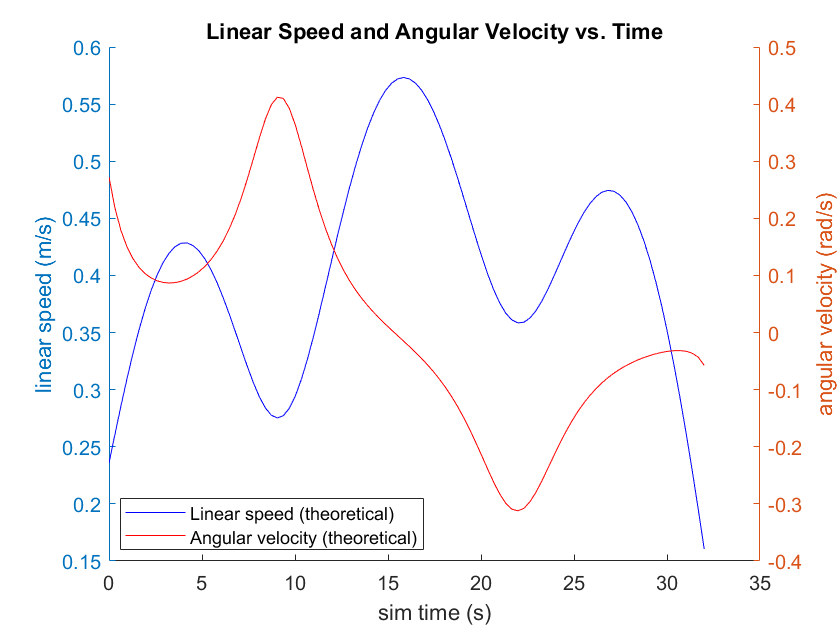

% Find angular velocity
omega = simplify(cross(T_hat, dT_hat));

% Find linear speed
speed = simplify(norm(dr)); % m/s, first derivative of position vector

% Plotting
t_num = linspace(0, 3.2/dilation, 100); % define a set of evenly spaced points between 0 and 3.2

% Initialize time, speed, and omega vectors
% t_values = [];
speed_values = [];
omega_values = [];

% Calculate values for speed and omega
for n=1:length(t_num)
    omega_plot = double(subs(omega, t, t_num(:,n)));
    
    % t_values(1,n) = n;
    speed_values(1,n) = double(subs(speed, t, t_num(:,n)));
    omega_values(1,n) = double(subs(omega(3), t, t_num(:,n)));
end

% Plot vectors
figure(3); clf; hold on
yyaxis left;
plot(t_num, speed_values, "b", "DisplayName", "Linear speed (theoretical)");
yyaxis right;
plot(t_num, omega_values, "r", "DisplayName", "Angular velocity (theoretical)");
legend("Location", "best");
xlabel("sim time (s)"); title("Linear Speed and Angular Velocity vs. Time");
yyaxis left; ylabel("linear speed (m/s)");
yyaxis right; ylabel("angular velocity (rad/s)");

2. After successfully traversing the bridge, use your encoder data measurements to compute the linear speed and angular velocity of your robot and add this to your plot.

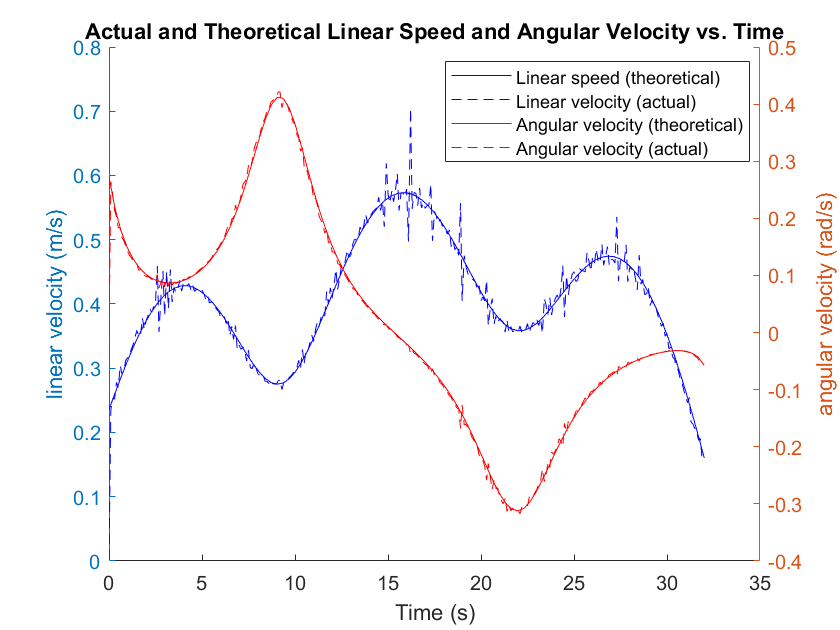

% Import 'encoder_data.csv' as column vectors

% Set parameter for distance between wheels
d = 0.235;      % m

% Find wheel velocities
velocityLeft = diff(encoderLeftmeters) ./ diff(timeseconds);
velocityRight = diff(encoderRightmeters) ./ diff(timeseconds);

% Find angular velocity
omega_actual = (velocityRight - velocityLeft) ./ d;  % rad/s

% Find linear speed
speed_actual = (velocityLeft + velocityRight) ./ 2; % m/s

% Plot vectors
figure(3); hold on;
yyaxis left;
plot(timeseconds(1:end-1,:), speed_actual, "b--", "DisplayName", "Linear velocity (actual)");
yyaxis right;
plot(timeseconds(1:end-1,:), omega_actual, "r--", "DisplayName", "Angular velocity (actual)");
legend("Location", "best");
xlabel("Time (s)"); title("Actual and Theoretical Linear Speed and Angular Velocity vs. Time");
yyaxis left; ylabel("linear velocity (m/s)");
yyaxis right; ylabel("angular velocity (rad/s)");

## **Exercise 21.3**

1. Compute and plot your robot's left and right wheel velocities as a function of time for the Bridge of Doom.

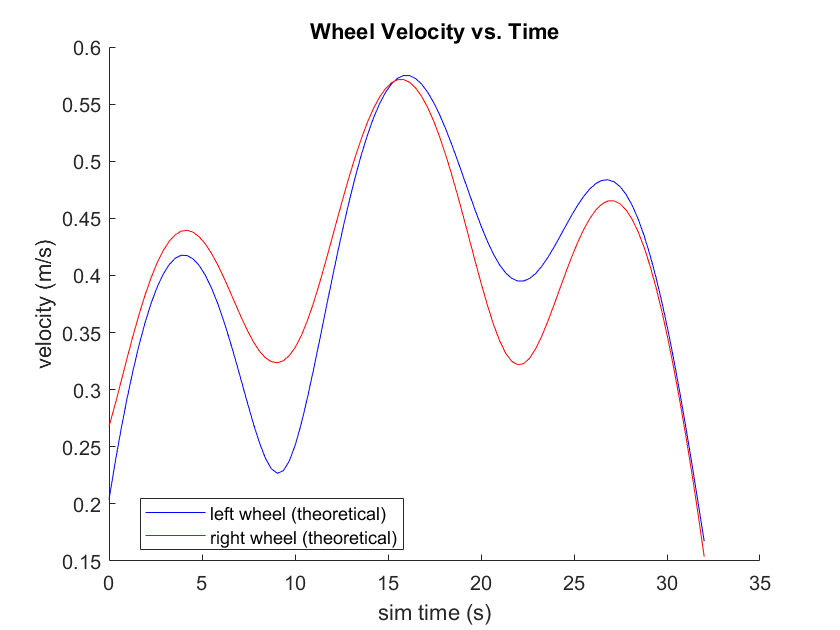

d_num = 0.235;  % m
V_left = simplify(speed - omega(1,3) * d_num / 2);
V_right = simplify(speed + omega(1,3) * d_num / 2);


% Initialize time, speed, and omega vectors
clf; figure();
left_values = [];
right_values = [];

% Calculate values for speed and omega
for n=1:length(t_num)
    left_values(1,n) = double(subs(V_left, t, t_num(:,n)));
    right_values(1,n) = double(subs(V_right, t, t_num(:,n)));
end

figure(2); clf; hold on;
plot(t_num, left_values, "b", "DisplayName", "left wheel (theoretical)");
plot(t_num, right_values, "r", "DisplayName", "right wheel (theoretical)");
title("Wheel Velocity vs. Time"); xlabel("sim time (s)"); ylabel("velocity (m/s)"); legend("Location", "best")

2. After successfully traversing the bridge, use your encoder data to compute the measured wheel velocities and add them to your plot.

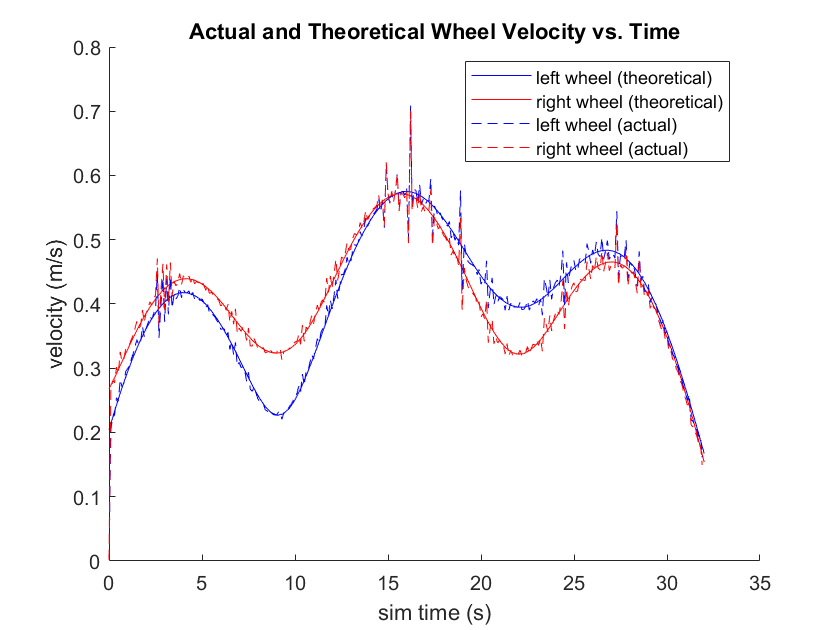

figure(2); hold on; legend("Location", "best")
plot(timeseconds(1:end-1,:), velocityLeft, "b--", "DisplayName", "left wheel (actual)");
plot(timeseconds(1:end-1,:), velocityRight, "r--", "DisplayName", "right wheel (actual)");
title("Actual and Theoretical Wheel Velocity vs. Time")

## **Exercise 21.4**

See `starterCodeForBridgeOfDoomQEA2021.m`

[Encoder](https://qeacourse.github.io/RoboNinjaWarrior/Sample_code/encoder_dataset_collector)

## **Exercise 21.5**

Map your robot’s predicted and actual path crossing the Bridge of Doom using encoder values as your robot traverses the bridge, convert that to coordinates and headings for the robot throughout its perilous journey. Use the Matlab quiver command to plot the predicted and experimental unit tangent vectors at various points along the curve (note: do not include an arrow for every time step or your plot will be too cluttered). The planned (theoretical) path should be plotted with a solid line, while the experimental result should be plotted with a dashed line. Make sure your plots include appropriate units, labels, and legends.

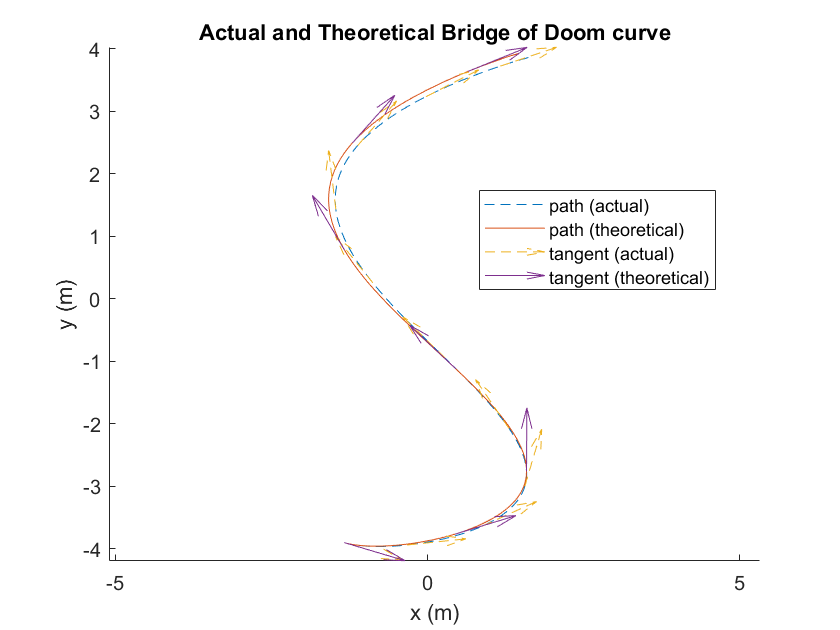

% Integrate the angular velocity to get theta
theta_integrated = cumtrapz(timeseconds(1:end-1,:), omega_actual);

% Calculate and adjust starting theta
shift_That = double(subs(T_hat, t, timeseconds(1)));
shift_theta = atan(shift_That(2)/shift_That(1));
theta_integrated = theta_integrated + shift_theta;

% Get speed components from actual speed
speed_x = speed_actual .* cos(theta_integrated);
speed_y = speed_actual .* sin(theta_integrated);

% Integrate speed components to get location coordinates
pos_x = cumtrapz(timeseconds(1:end-1,:), speed_x);
pos_y = cumtrapz(timeseconds(1:end-1,:), speed_y);
location_actual = [pos_x pos_y]';

% Calculate the starting position
shift_r = double(subs(r, t, timeseconds(1)));

% Adjusting for starting position
location_actual(1,:) = location_actual(1,:) + shift_r(1);
location_actual(2,:) = location_actual(2,:) + shift_r(2);

% Calculate tangents
T_hat_u = cos(theta_integrated); %speed_x ./ norm(speed_x);
T_hat_v = sin(theta_integrated); %speed_y ./ norm(speed_y);
% T_hat_u = speed_x ./ sqrt(speed_x.^2 + speed_y.^2);
% T_hat_v = speed_y ./ sqrt(speed_x.^2 + speed_y.^2);
x_vector = [];
y_vector = [];
u_vector = [];
v_vector = [];

% Plotting the position curve test
figure(11); clf; hold on; legend("Location", "best")
title("Actual and Theoretical Bridge of Doom curve"); xlabel("x (m)"); ylabel("y (m)");

figure(11); hold on; plot(location_actual(1,:), location_actual(2,:), "--", "DisplayName", "path (actual)"); axis equal;

fplot(r(1),r(2),[0,3.2/dilation],"DisplayName","path (theoretical)")
for i=1:30:328
    x_vector(i,1) = location_actual(1,i);
    y_vector(i,1) = location_actual(2,i);
    u_vector(i,1) = T_hat_u(i,:);
    v_vector(i,1) = T_hat_v(i,:);
end

scale = 2;

quiver(x_vector(:,1), y_vector(:,1),u_vector(:,1),v_vector(:,1), scale, "--", "DisplayName", "tangent (actual)"); hold on;

r_num = [];
T_hat_num = [];

for n=1:15:length(t_num)
     r_num(n,:) = double(subs(r, t, t_num(:,n)));
     T_hat_num(n,:) = double(subs(T_hat, t, t_num(:,n)));     
end

quiver(r_num(:,1), r_num(:,2), T_hat_num(:,1), T_hat_num(:,2), 1.2, "DisplayName", "tangent (theoretical)") % plot the unit tangent